# 802.11 Ideal Rate Adaptation Algorithm/Rate Control Algorithm

This example shows Ideal Rate Adaptation Algorithm by varying the Modulation and Coding scheme (MCS) of successive packets transmitted over a frequency selective multipath fading channel.

## Introduction

The IEEE® 802.11™ standard supports  Ideal Rate Adaptation Algorithm by adjusting the MCS value of each transmitted packet based on the underlying radio propagation channel. Maximizing link throughput, in a propagation channel that is time varying due to multipath fading or movement of the surrounding objects, requires dynamic variation of MCS. The IEEE 802.11 standard does not define any standardized rate adaptation algorithm/rate control algorithm (RAA/RCA) for dynamically varying the modulation rate. The implementation of RAA is left open to the WLAN device manufacturers. This example uses a closed-loop rate control scheme. A recommended MCS for transmitting a packet is calculated at the receiver and is available at the transmitter without any feedback latency. The SNR is fed back from the receiver to the transmitter via a perfect out-of-band mechanism. The MCS is adjusted for each subsequent packet in response to an evolving channel condition with noise power varying over time.

## Overview of Ideal RAA

In this RAA, it initially creates a table of SNR and MCS pairs. To generate SNR and MCS pairs physical layer simulations from [`802.11ac Packet Error Rate Simulation for 8x8 TGac Channel`](https://in.mathworks.com/help/wlan/ug/802-11ac-packet-error-rate-simulation-for-8x8-tgac-channel.html) is been used. The SNR thresholds in this table ensure selecting an MCS that leads to a PER below a certain value. In the example the algorithm is designed for PER<=0.1. The SNR is fed back from the receiver to the transmitter via a perfect out-of-band mechanism (thus the name ‘ideal’). The main drawback of this mechanism is the use of an out-of-band channel for sending back the feedback which is not available in Industrial, Scientific, and Medical (ISM) bands used by IEEE 802.11. Stationary setup of the system is used for the simulations.

 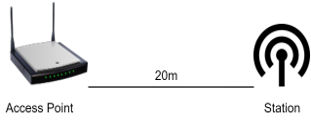

## Matlab Implementation

In this example, an IEEE 802.11ac™ [ [1](https://in.mathworks.com/help/wlan/ug/802-11-dynamic-rate-control-simulation.html#TransmitRateControlExample-11) ] waveform consisting of a single VHT format packet is generated using the [`wlanWaveformGenerator`](https://in.mathworks.com/help/wlan/ref/wlanwaveformgenerator.html) function. The waveform is passed through a TGac channel and noise is added. The packet is synchronized and decoded to recover the PSDU. The SNR is estimated and compared against thresholds to determine which MCS is suitable for transmission of the next packet. This figure shows the processing for each packet.

 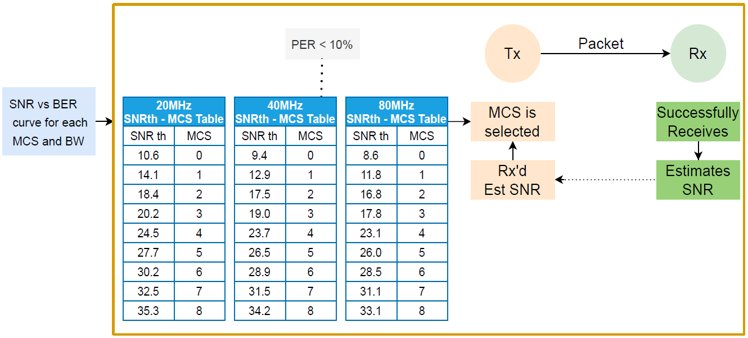

## **Waveform Configuration**

An IEEE 802.11ac VHT transmission is simulated in this example. The VHT waveform properties are specified in a [`wlanVHTConfig`](https://in.mathworks.com/help/wlan/ref/wlanvhtconfig.html) configuration object. In this example the object is initially configured for a 40 MHz channel bandwidth, single transmit antenna and MCS-0. The MCS for the subsequent packets is changed by the algorithm throughout the simulation.

cfgVHT = wlanVHTConfig;            % Create wlanVHTConfig object
cfgVHT.ChannelBandwidth = 'CBW40'; % 40 MHz channel bandwidt
cfgVHT.NumTransmitAntennas = 1;    % transmit antennas
cfgVHT.NumSpaceTimeStreams = 1;    % Spatial Streams
cfgVHT.MCS = 0;                    % QPSK rate-1/2
cfgVHT.APEPLength = 4096;          % APEP length in bytes

% Set random stream for repeatability of results
rng(0,'combRecursive')
s = rng;

## **Channel Configuration**

In this example a TGac N-LOS channel model is used with delay profile Model-D. For Model-D when the distance between the transmitter and receiver is greater than or equal to 10 meters, the model is NLOS. This is described further in [`wlanTGacChannel`](https://in.mathworks.com/help/wlan/ref/wlantgacchannel-system-object.html).


tgacChannel = wlanTGacChannel;
tgacChannel.DelayProfile = 'Model-D';
tgacChannel.NumTransmitAntennas = 1;
tgacChannel.NumReceiveAntennas = 1;
tgacChannel.TransmitReceiveDistance = 20; % Distance in meters for NLOS
tgacChannel.ChannelBandwidth = cfgVHT.ChannelBandwidth;
tgacChannel.LargeScaleFadingEffect = 'None';

% Set the sampling rate for the channel
sr = wlanSampleRate(cfgVHT);
tgacChannel.SampleRate = sr; 


## Rate Control Algorithm Parameters

Typically RCAs use channel quality or link performance metrics, such as SNR or packet error rate, for rate selection. The RCA presented in this example estimates the SNR of a received packet. On reception, the estimated SNR is compared against a thresholds from the physical layer simulations. If the SNR exceeds/succeeds the threshold value, then a new MCS is selected for transmitting the next packet.

snrth = [10.6 14.1 18.4 20.2 24.5 27.7 30.2 32.5 35.35];   %SNR thresolds for 20MHz channel BW
% snrth = [9.5 12.9 17.7 19.0 23.7 26.5 28.9 31.5 34.2];     %SNR thresolds for 40MHz channel BW
% snrth = [8.6 11.8 16.9 17.8 23.2 26.0 28.5 31.1 33.1];      %SNR thresolds for 80MHz channel BW

mcsval = [0 1 2 3 4 5 6 7 8];

## **Simulation Parameters**

In this simulation `numPackets` packets are transmitted through a TGac channel, separated by a fixed idle time. The channel state is maintained throughout the simulation, therefore the channel evolves slowly over time. This evolution slowly changes the resulting SNR measured at the receiver. Since the TGac channel changes very slowly over time, here an SNR variation at the receiver visible over a short simulation can be forced using the `walkSNR` parameter to modify the noise power:

Setting `walkSNR` to true generates a varying SNR by randomly setting the noise power per packet during transmission. The SNR walks between 14-35 dB (using the `amplitude` and `meanSNR` variables).

Setting `walkSNR` to false fixes the noise power applied to the received waveform, so that channel variations are the main source of SNR changes at the receiver.

numPackets = 1000; % Number of packets transmitted during the simulation 
walkSNR = true;

% Select SNR for the simulation
if walkSNR
    meanSNR = 25;   % Mean SNR
    amplitude = 14; % Variation in SNR around the average mean SNR value
    % Generate varying SNR values for each transmitted packet
    baseSNR = sin(linspace(1,10,numPackets))*amplitude+meanSNR;
    snrWalk = baseSNR(1); % Set the initial SNR value
    % The maxJump controls the maximum SNR difference between one
    % packet and the next 
    maxJump = 0.5;
else
    % Fixed mean SNR value for each transmitted packet.
    % in SNR comes from a time varying radio chan All the variabilitynel
    snrWalk = 22; %#ok<UNRCH>
end

% To plot the equalized constellation for each spatial stream set
% displayConstellation to true
displayConstellation = false;
if displayConstellation
    ConstellationDiagram = comm.ConstellationDiagram; %#ok<UNRCH>
    ConstellationDiagram.ShowGrid = true;
    ConstellationDiagram.Name = 'Equalized data symbols';
end

% Define simulation variables
snrMeasured = zeros(1,numPackets);
MCS = zeros(1,numPackets);
ber = zeros(1,numPackets);
nbiterr = zeros(1,numPackets);
packetError = zeros(1,numPackets);
bitError = zeros(1,numPackets);
packetLength = zeros(1,numPackets);
PER = zeros(1,numPackets);
rxlenght = zeros(1,numPackets);
Rxlength = zeros(1,numPackets);


## **Processing Chain**

The following processing steps occur for each packet:

- A PSDU is created and encoded to create a single packet waveform.

- A fixed idle time is added between successive packets.

- The waveform is passed through an evolving TGac channel.

- AWGN is added to the transmitted waveform to create the desired average SNR per active subcarrier after OFDM demodulation.

- This local function `processPacket` passes the transmitted waveform through the TGac channel, performs receiver processing, and SNR estimation.

- The VHT-LTF is extracted from the received waveform. The VHT-LTF is OFDM demodulated and channel estimation is performed.

- The VHT Data field is extracted from the synchronized received waveform.

- Noise estimation is performed using the demodulated data field pilots and single-stream channel estimate at pilot subcarriers.

- The estimated SNR for each packet is compared against the threshold, the comparison is used to adjust the MCS for the next packet.

- The PSDU is recovered using the extracted VHT-Data field.

For simplicity, this example assumes:

- Fixed bandwidth and antenna configuration for each transmitted packet.

- There is no explicit feedback packet to inform the transmitter about the suggested MCS setting for the next packet. The example assumes that this information is known to the transmitter before transmitting the subsequent packet.

- Fixed idle time of 0.5 milliseconds between packets.

for numPkt = 1:numPackets 
    if walkSNR
        % Generate SNR value per packet using random walk algorithm biased
        % towards the mean SNR
        snrWalk = baseSNR(numPkt);
    end

    % Generate a single packet waveform
    txPSDU = randi([0,1],8*cfgVHT.PSDULength,1,'int8');
    txWave = wlanWaveformGenerator(txPSDU,cfgVHT,'IdleTime',5e-4);
    
    numPacketErrors = 0;
    
    % Receive processing, including SNR estimation
    y = processPacket(txWave,snrWalk,tgacChannel,cfgVHT,numPacketErrors);
    
    % Plot equalized symbols of data carrying subcarriers
    if displayConstellation && ~isempty(y.EstimatedSNR)
        release(ConstellationDiagram);
        ConstellationDiagram.ReferenceConstellation = wlanReferenceSymbols(cfgVHT);
        ConstellationDiagram.Title = ['Packet ' int2str(numPkt)];
        ConstellationDiagram(y.EqDataSym(:));
        drawnow 
    end
    
    % Store estimated SNR value for each packet
    if isempty(y.EstimatedSNR) 
        snrMeasured(1,numPkt) = NaN;
    else
        snrMeasured(1,numPkt) = y.EstimatedSNR;
    end
    
    % Determine the length of the packet in seconds including idle time
    packetLength(numPkt) = y.RxWaveformLength/sr;
    Rxlength(numPkt) = (y.RxWaveformLength);
    rxlenght(numPkt) = length(y.RxPSDU);
    
    % Calculate packet error rate (PER)
    if isempty(y.RxPSDU)
        % Set the PER of an undetected packet to NaN
        ber(numPkt) = NaN;
        nbiterr(numPkt) = 1;
    else
        [nbiterr(numPkt),ber(numPkt)] = biterr(y.RxPSDU,txPSDU);
    end
   
     bitError(numPkt) = any(nbiterr(numPkt));
     PER(numPkt) = y.NPE+bitError(numPkt);
     
    
    % Compare the estimated SNR to the threshold, and adjust the MCS value
    % used for the next packet
    MCS(numPkt) = cfgVHT.MCS; % Store current MCS value

% Different logic to achieve the same 
%     for in = 1:9
%            if ( snrMeasured > snrth(in))
%                ind1 = in-1;
%            end
%         MCSind = ind1;
%     end
     
    for in = 1:9
       if(snrMeasured(numPkt) > snrth(in))  % baseSNR  %snrMeasured
               MCSind = mcsval(in);
       end
    end
    cfgVHT.MCS = MCSind;
end

'helperFrequencyOffset' is used in the following examples:
  Recover and Analyze Packets in 802.11 Waveform
  802.11ad Packet Error Rate Single Carrier PHY Simulation with TGay Channel
  802.11ax Downlink Throughput Comparison of OFDM and OFDMA Through System-level Simulation
  802.11be 4096-QAM 320 MHz Waveform Generation and Analysis
  


tpppkt = (8*cfgVHT.APEPLength.*(ber==0))./(packetLength)/1e6;
sumtps = sum(tpppkt);
avgtp = sumtps/numPackets;

PE = sum(PER)/numPackets;

mcsz = 0; perz = 0;
mcsone = 0; perone = 0;
mcstwo = 0; pertwo = 0;
mcsthree = 0; perthree = 0;
mcsfour = 0; perfour = 0;
mcsfive = 0; perfive = 0;
mcssix = 0; persix = 0;
mcsseven = 0; perseven = 0;
mcseight = 0; pereight = 0;

% Evaluating PER for each MCS
for n = 1:numPackets
    if MCS(n)== 0
        mcsz = mcsz+1;
        if PER(n) == 1
           perz = perz +1;
        end
    elseif MCS(n)== 1
        mcsone = mcsone+1;
        if PER(n) == 1
           perone = perone +1;
        end
    elseif MCS(n)== 2
        mcstwo = mcstwo+1;
        if PER(n) == 1
           pertwo = pertwo +1;
        end
    elseif MCS(n)== 3
        mcsthree = mcsthree+1;
        if PER(n) == 1
           perthree = perthree +1;
        end
    elseif MCS(n)== 4
        mcsfour = mcsfour+1;
        if PER(n) == 1
           perfour = perfour +1;
        end
    elseif MCS(n)== 5
        mcsfive = mcsfive+1;
        if PER(n) == 1
           perfive = perfive +1;
        end
    elseif MCS(n)== 6
        mcssix = mcssix+1;
        if PER(n) == 1
           persix = persix +1;
        end
    elseif MCS(n)== 7
        mcsseven = mcsseven+1;
        if PER(n) == 1
           perseven = perseven +1;
        end
    else 
        mcseight = mcseight+1;
        if PER(n) == 1
           pereight = pereight +1;
        end
    end
end

pktspMCS = [mcsz mcsone mcstwo mcsthree mcsfour mcsfive mcssix mcsseven mcseight];
totalpkts = sum (pktspMCS);

PERpMCS = [perz perone pertwo perthree perfour perfive persix perseven pereight];
totalpers = sum(PERpMCS);

MCSpPER =  PERpMCS./pktspMCS;

## **Display and Plot Simulation Results**

This example plots the variation of MCS, SNR, BER, and data throughput over the duration of the simulation.

- The MCS used to transmit each packet is plotted. When compared to the estimated SNR, you can see the MCS selection is dependent on the estimated SNR.

- The bit error rate per packet depends on the channel conditions, SNR, and MCS used for transmission.

- The throughput is maximized by varying the MCS according to the channel conditions. The throughput is calculated using a sliding window of three packets. For each point plotted, the throughput is the number of data bits, successfully recovered over the duration of three packets. The length of the sliding window can be increased to further smooth the throughput. You can see drops in the throughput either when the MCS decreases or when a packet error occurs.

% Display and plot simulation results
% disp(['Overall data rate: ' num2str(8*cfgVHT.APEPLength*(numPackets-numel(find(ber)))/sum(packetLength)/1e6) ' Mbps']);
% disp(['Overall packet error rate: ' num2str(numel(find(ber))/numPackets)]);
disp(['Channel BW: ' cfgVHT.ChannelBandwidth]);
disp(['Ideal Average TP: ' num2str(avgtp) ' Mbps']);
disp(['Ideal Average PER: ' num2str(PE)]);

X = plotResults(ber,packetLength,snrMeasured,MCS,cfgVHT,bitError,baseSNR,MCSpPER,pktspMCS,PERpMCS);

TP = X.movDataRate;

% Restore default stream
rng(s);


## **Conclusion and Further Exploration**

This example uses a closed-loop rate control scheme where knowledge of the MCS used for subsequent packet transmission is assumed to be available to the transmitter.

In this example the variation in MCS over time due to the received SNR is controlled by the `threshold` values from physical layer simulations designed for packet error rate of 10%.

Try setting the `displayConstellation` to true in order to plot the equalized symbols per received packet, you can see the modulation scheme changing over time. Also try setting `walkSNR` to false in order to visualize the MCS change per packet. Here the variability in SNR is only caused by the radio channel, rather than the combination of channel and random walk.Ideal algorithm can detect channel changes faster than other algorithms and adapts the rate accordingly. 

Ideal algorithm can detect channel changes faster than other algorithms and adapts the rate accordingly. 

Further exploration includes using an alternate RCA scheme, more realistic MCS variation including changing number of space time streams, packet size and enabling STBC for subsequent transmitted packets.

**Appendix**

This example uses the following helper functions:

- [vhtNoiseEstimate.m](matlab:edit('vhtNoiseEstimate.m'))

- [vhtSingleStreamChannelEstimate.m](matlab:edit('vhtSingleStreamChannelEstimate.m'))

**Selected Bibliography**

- IEEE Std 802.11ac™-2013 IEEE Standard for Information technology - Telecommunications and information exchange between systems - Local and metropolitan area networks - Specific requirements - Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications - Amendment 4: Enhancements for Very High Throughput for Operation in Bands below 6 GHz.

**Local Functions**

The following local functions are used in this example:

- `processPacket`: Add channel impairments and decode receive packet

- `plotResults`: Plot the simulation results

function Y = processPacket(txWave,snrWalk,tgacChannel,cfgVHT,numPacketErrors)
    % Pass the transmitted waveform through the channel, perform
    % receiver processing, and SNR estimation.
    sr = wlanSampleRate(cfgVHT);
    
    chanBW = cfgVHT.ChannelBandwidth; % Channel bandwidth
    % Set the following parameters to empty for an undetected packet
    estimatedSNR = [];
    eqDataSym = [];
    noiseVarVHT = [];
    rxPSDU = [];
        
    % Get the OFDM info
    ofdmInfo = wlanVHTOFDMInfo('VHT-Data',cfgVHT);
    
    % Create an instance of the AWGN channel for each transmitted packet
    awgnChannel = comm.AWGNChannel;
    awgnChannel.NoiseMethod = 'Signal to noise ratio (SNR)';
    % Normalization
    awgnChannel.SignalPower = 1/tgacChannel.NumReceiveAntennas;
    % Account for energy in nulls
    awgnChannel.SNR = snrWalk-10*log10(ofdmInfo.FFTLength/ofdmInfo.NumTones);
    
    % Pass the waveform through the fading channel model
    reset(tgacChannel);
    rxWave = tgacChannel(txWave);
    
    % Add noise
    rxWave = awgnChannel(rxWave);
    rxWaveformLength = size(rxWave,1); % Length of the received waveform
    
    % Recover packet
    ind = wlanFieldIndices(cfgVHT); % Get field indices
    coarsePktOffset = wlanPacketDetect(rxWave,chanBW); % Detect packet
    if isempty(coarsePktOffset) % If empty no L-STF detected; packet error
        numPacketErrors = numPacketErrors+1;
    end
    
    if ~isempty(coarsePktOffset) % If packet detected 
        lstf = rxWave(coarsePktOffset+(ind.LSTF(1):ind.LSTF(2)),:); 
        coarseFreqOff = wlanCoarseCFOEstimate(lstf,cfgVHT.ChannelBandwidth);
        rxWave = helperFrequencyOffset(rxWave,sr,-coarseFreqOff);
        
        % Extract the L-LTF field for fine timing synchronization
        nonhtfields = rxWave(coarsePktOffset+(ind.LSTF(1):ind.LSIG(2)),:);
        finePktOffset = wlanSymbolTimingEstimate(nonhtfields,chanBW);
     
        % Determine final packet offset
        pktOffset = coarsePktOffset+finePktOffset;
        
        if pktOffset>50
            numPacketErrors = numPacketErrors+1;
        end
        
        if pktOffset<15 % If synchronization successful
            % Extract VHT-LTF samples from the waveform, demodulate and
            % perform channel estimation
            lltf = rxWave(pktOffset+(ind.LLTF(1):ind.LLTF(2)),:); 
            fineFreqOff = wlanFineCFOEstimate(lltf,cfgVHT.ChannelBandwidth);
            rxWave = helperFrequencyOffset(rxWave,sr,-fineFreqOff);
            
            VHTLTF = rxWave(pktOffset+(ind.VHTLTF(1):ind.VHTLTF(2)),:);
            demodVHTLTF = wlanVHTLTFDemodulate(VHTLTF,cfgVHT);
            
            chanEstVHTLTF = wlanVHTLTFChannelEstimate(demodVHTLTF,cfgVHT);

            % Get single stream channel estimate
            chanEstSSPilots = vhtSingleStreamChannelEstimate(demodVHTLTF,cfgVHT);
            
            
            % Extract VHT data field
            vhtdata = rxWave(pktOffset+(ind.VHTData(1):ind.VHTData(2)),:);
            
            % Estimate the noise power in VHT data field
            noiseVarVHT = vhtNoiseEstimate(vhtdata,chanEstSSPilots,cfgVHT);
            
            % Recover equalized symbols at data carrying subcarriers using
            % channel estimates from VHT-LTF
            [rxPSDU,~,eqDataSym] = wlanVHTDataRecover(vhtdata,chanEstVHTLTF,noiseVarVHT,cfgVHT);
            if isempty(rxPSDU)
                numPacketErrors = numPacketErrors+1;
            end
                        
            % SNR estimation per receive antenna
            powVHTLTF = mean(VHTLTF.*conj(VHTLTF));
            estSigPower = powVHTLTF-noiseVarVHT;
            estimatedSNR = 10*log10(mean(estSigPower./noiseVarVHT));
        end
    end
    
    % Set output
    Y = struct( ...
        'RxPSDU',           rxPSDU, ...
        'EqDataSym',        eqDataSym, ...
        'RxWaveformLength', rxWaveformLength, ...
        'NoiseVar',         noiseVarVHT, ...
        'NPE',              numPacketErrors,...
        'EstimatedSNR',     estimatedSNR);
    
end

function x = plotResults(ber,packetLength,snrMeasured,MCS,cfgVHT,bitError,baseSNR,MCSpPER,pktspMCS,PERpMCS)

    f1 = figure;
    subplot(3,1,1);
    stem(MCSpPER,'r');                                              
    grid on;
    grid minor;
    ylabel('PER')
    xticklabels({'0',' 1',' 2',' 3',' 4',' 5',' 6',' 7 ','8'})
    title('PERs for each MCS')
    
    subplot(3,1,2);
    bar(pktspMCS);
    grid on;
    grid minor;
    ylabel('Packets')
    xticklabels({'0',' 1',' 2',' 3',' 4',' 5',' 6',' 7 ','8'})
    title('Packets simulated for each MCS')
    
    subplot(3,1,3);
    stem(PERpMCS,'g');
    grid on;
    grid minor;
    ylabel('Packets')
    xlabel('MCS')
    xticklabels({'0',' 1',' 2',' 3',' 4',' 5',' 6',' 7 ','8'})
    title('Packet errors for each MCS')
    
   
    a = 4;
    % Visualize simulation results
    f2 = figure('Outerposition',[50 50 900 700]);
    
    subplot(a,1,1);
    plot(baseSNR,'r');
%     plot(snrMeasured);
    grid on;
    ylabel('SNR')
    title('SNR')  %Estimated  Transmitted

%     subplot(a,1,1);
%     plot(baseSNR,'r');
%     ylabel('SNR')
%     title(' SNR') 

    subplot(a,1,2);
%     plot(MCS,'r');
    plot(MCS);
    grid on;
    ylabel('MCS')
    title('MCS selected for transmission')   
    
    subplot(a,1,3);
    windowLength = 1; % Length of the averaging window
    movDataRate = movsum(8*cfgVHT.APEPLength.*(ber==0),windowLength)./movsum(packetLength,windowLength)/1e6; 
    plot(movDataRate)
%     plot(movDataRate,'r')
    grid on;
    ylabel('Mbps')
    %title(('Throughput each packet'))
    title(sprintf('Throughput over last %d packet',windowLength))
    
    subplot(a,1,4);
    stem(find(bitError>0),bitError(bitError>0),'LineStyle','-','Marker','x')
%     stem(find(bitError>0),bitError(bitError>0),'xr')
    grid on;
    xlabel('Packet Number')
    ylabel('PER')
    title('Packet errors')  
   
%     subplot(a,1,6);
%     plot(baseSNR,'r');
%     ylabel('SNR')
%     title('SNR generated')
    
%     subplot(a,1,4);
%     plot(find(ber==0),ber(ber==0),'x')
%     hold on; stem(find(ber>0),ber(ber>0),'or')
%     if any(ber)
%         legend('Successful decode','Unsuccessful decode')
%     else
%         legend('Successful decode')
%     end
%     xlabel('Packet Number')
%     ylabel('BER')
%     title('Instantaneous bit error rate per packet')
    x = struct( ...
      'movDataRate',     movDataRate);  
end

*Copyright 2021-2022, The IISc team:* 

**Researcher and Developer:** Shyam Sundar D G  [shyamsdg01@gmail.com](shyamsdg01@gmail.com)

**Technical Advisors:** *Neeleshb Mehta *[*nbmehta@iisc.ac.in*](nbmehta@iisc.ac.in)* and *Chandramani Singh [chandra@iisc.ac.in](chandra@iisc.ac.in)

*The authors would like to thank* ***Aerospace Network Research Consortium(***[ANRC](http://www.anrc.us/)***), ***[IISc](https://iisc.ac.in/)* for thier support.*